# 1D Muscle Model based on the **Hill** 2-Element Model

clear all

## Model Overview

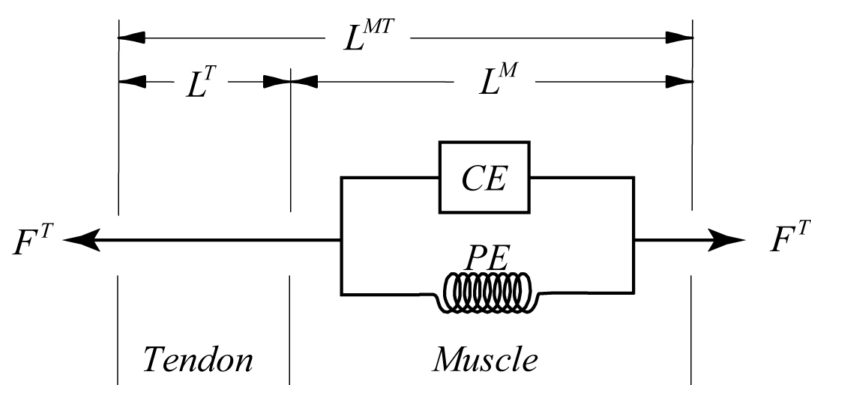

Schematic taken from: Anderson, C. (2007). Physics-based Simulation of Biological Structures Equations for Modeling the Forces Generated by Muscles and Tendons. In *BIOE215*. Stanford.

Global plotting options

fnum = 1;
opt_grid = 'on';
opt_hold =  'off';
splotx = 0;
sploty = 0;

## Global muscle properties

$L_{rest}$ is the muscle resting length, $P_{max}$ is the maximum force the muscle can produce and $v_{max}$ is the maximum velocity of shortening.

L_REST = 0.5; %mm
F_MAX = 5; %N
V_MAX = 1.5; %mm/s

$a$ and $b$ are shape constants for the muscle force-velocity relationship

% muscle model constants
a = 0.25;
b = a*V_MAX/F_MAX;

## Parallel elastic element

This element represents the passive response of the muscle upon streching greater than resting length.

Note that $L_{PE}=L_{TOT}=L_{CE}$

The form of the passive relationship is not easily found in literature and is implemented in a straight forward way here to match the requirements of an exponential form which is non-zero above $L_{rest}$;


$$F_{PE} = F_{MAX}c \times [e^{L_{TOT}/L{REST}-1}-1]$$


Parameter $c$ is introduced to tune the shape of the curve. 

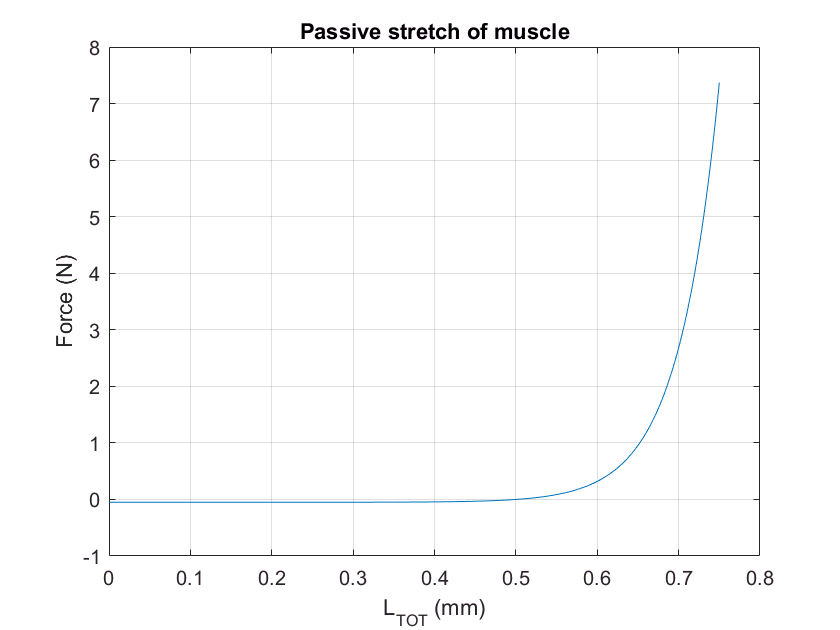

c = 0.01;
d = 10;
L_TOT = (0:0.001:L_REST*1.5);
F_PE = F_MAX*c*(exp(d*(L_TOT/L_REST-1))-1);

xvec = L_TOT;
yvec = F_PE;
ftitle = 'Passive stretch of muscle';
xtitle = 'L_{TOT} (mm)';
ytitle = 'Force (N)';
plotxy(xvec, yvec, fnum, ftitle, xtitle, ytitle, opt_grid, opt_hold, ...
    splotx, sploty)

## Contractile element

This element is reponsible for the active force production in the muscle. The total force is given in the form;


$$F_{CE} = \alpha(t) \times F_{vel}(V)\times F_{len}(L_{TOT})$$


As a first step, we assume that the muscle is fully tetanized, i.e. $\alpha(t) = 1$. 

Force-velocity 

Taken from *"Muscle modelling basics"* by Challis, J. (1994), who based it on on Hill (1938);


$$F_{VEL} = \frac{a(V_{MAX}-V)}{(b-V)}$$


where $a$ and $b$ have been fit to $V_{MAX}$ and $F_{MAX}$.

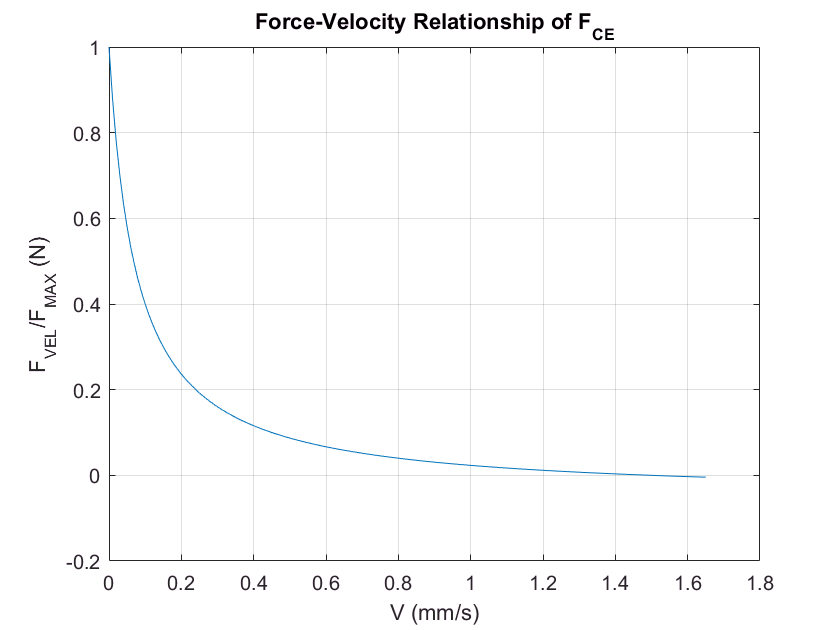

V = 0:0.01:1.1*V_MAX;
F_VEL = a*(V_MAX-V)./(b+V);
% normalize the F-v relationship to maximum force
F_VEL = F_VEL/F_MAX;

xvec = V;
yvec = F_VEL;
ftitle = 'Force-Velocity Relationship of F_{CE}';
xtitle = 'V (mm/s)';
ytitle = 'F_{VEL}/F_{MAX} (N)';
plotxy(xvec, yvec, fnum, ftitle, xtitle, ytitle, opt_grid, opt_hold, ...
    splotx, sploty)

Force-Length

The force-length relationship is also taken from *"Muscle modelling basics"* by Challis, J. (1994), who based it on on Hatze (1981);


$$F_{LEN}=F_{MAX}[e^{-(\frac{Q-1}{SK})^2}]$$


where $Q = L_{CE}/L_{REST}$ and$SK$ is a material parameter.

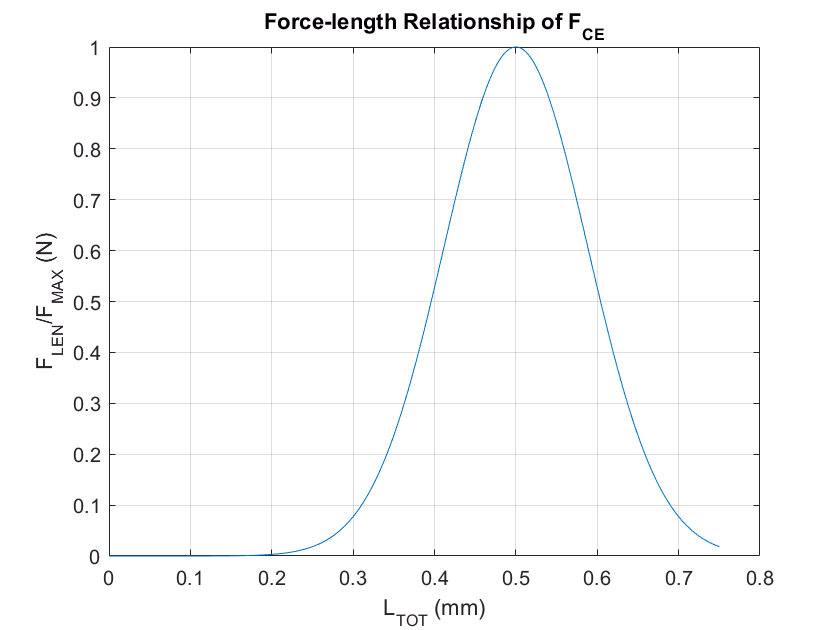

SK = 0.25;
% L_TOT is defined above, the same definition is used here
Q = L_TOT/L_REST;
F_LEN = F_MAX*exp(-((Q-1)/SK).^2);
% normalise the F-l relationship to max force
F_LEN = F_LEN/F_MAX;

L_TOT = (0:0.001:L_REST*1.5);
xvec = L_TOT;
yvec = F_LEN;
ftitle = 'Force-length Relationship of F_{CE}';
xtitle = 'L_{TOT} (mm)';
ytitle = 'F_{LEN}/F_{MAX} (N)';
plotxy(xvec, yvec, fnum, ftitle, xtitle, ytitle, opt_grid, opt_hold, ...
    splotx, sploty)

Now, returning to the contractile elment total force (normalising the indiviual relatioships to maximum force); 


$$F_{CE} = F_{MAX} \times \frac{a(V_{MAX}-V)}{(b-V)F_{MAX}} \times e^{-(\frac{L_{CE}/L_{REST}-1}{SK})^2}$$


recall that the muscle is currently fully tetanised. 

## Total muscle force

Total force of the muscle is given by summing the passive and active parts; 


$$F_{MUSC} = F_{CE}+F_{PE}$$



$$F_{MUSC} =  F_{MAX} \times \{ \frac{a(V_{MAX}-V)}{(b-V)F_{MAX}} \times e^{-(\frac{L_{CE}/L_{REST}-1}{SK})^2} + c[e^{L_{TOT}/L{REST}-1}-1] \}$$


Constant velocity

Now, consider the muscle shortening at a constant velocity.

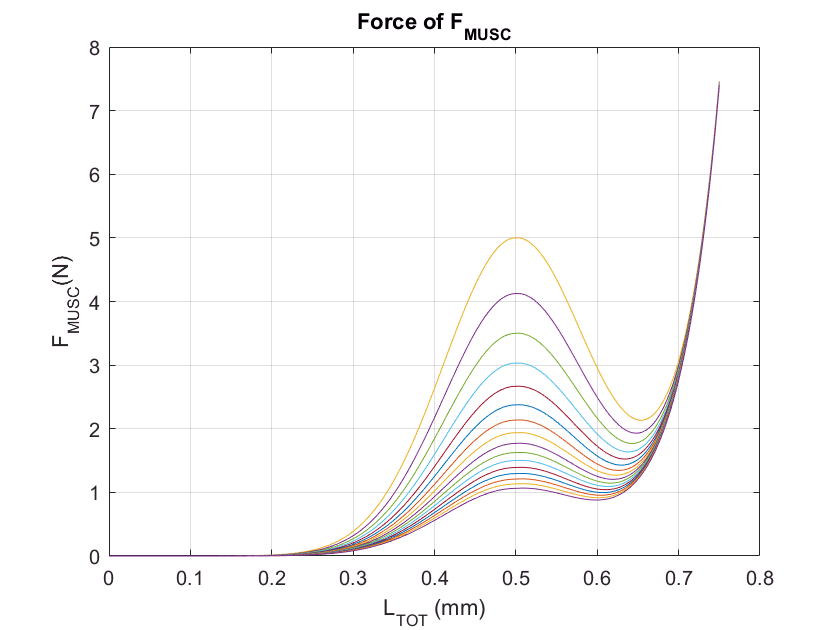

for i = 0:0.1:V_MAX
    V = (i/10)*V_MAX;
    F_VEL = a*(V_MAX-V)./(F_MAX*(b+V));
    Q = L_TOT/L_REST;
    F_LEN = exp(-((Q-1)/SK).^2);
    F_CE = F_MAX*F_VEL*F_LEN;
    F_PE = F_MAX*c*(exp(d*(L_TOT/L_REST-1))-1);
    F_MUSC = F_CE + max(F_PE,0);
    
    xvec = L_TOT;
    yvec = F_MUSC;
    ftitle = 'Force of F_{MUSC}';
    xtitle = 'L_{TOT} (mm)';
    ytitle = 'F_{MUSC}(N)';
    opt_hold = 'on';
    plotxy(xvec, yvec, fnum, ftitle, xtitle, ytitle, opt_grid, opt_hold, ...
        splotx, sploty)
    
end

Isometric Contraction

Now, consider an isometric contraction, that is, velocity = 0. How does the force evolve over time?

V = 0;
